clc
close all
% tic
format short 
rng('default') 

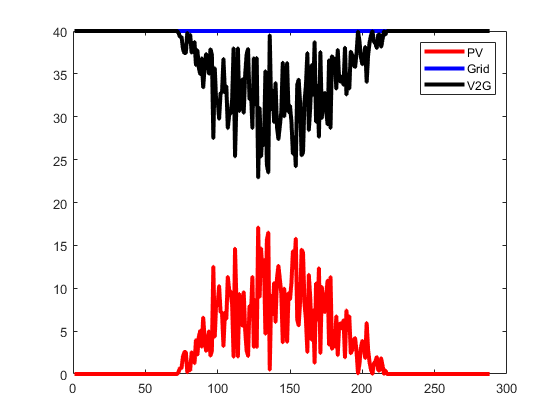

%% PV
pvPow = readmatrix('generated_pv_data.xls');
pvPow = pvPow/10;

%% Load
loadPow = readmatrix('generated_load_data.xls');
loadPow  = loadPow/100;
%% essPow, pvPow, loadPow, gridPow


essPow = randi([10,35],1,288);
% gridPow = randi([10,15],1,288);
gridPow = 40*ones(1,288);
% V2G amount 

v2gCapacity =  zeros(1, 288);
for tv2gCapacityindex = 1: size(v2gCapacity, 2)
    if(gridPow(tv2gCapacityindex)-pvPow(tv2gCapacityindex) > 0) 
        v2gCapacity(tv2gCapacityindex) = gridPow(tv2gCapacityindex)-pvPow(tv2gCapacityindex);
    end
end
plot(pvPow, 'linewidth', 3, 'color', 'r')
hold on
plot(gridPow, 'linewidth', 3, 'color', 'b')
hold on
plot(v2gCapacity, 'linewidth', 3, 'color', 'k')

legend('PV','Grid', 'V2G')